% import confusionmatStats function
addpath('C:\Users\Diego\Desktop\matprojects\funciones');

stroke=readtable('C:\Users\Diego\OneDrive - Universidad Autonoma de Madrid\metodologia\TECNOLOGIA DEL CONOCIMIENTO\datos_TC\stroke2.csv');

features=stroke(:,["age","avg_glucose_level","hypertension", ...
    "smoking_status","heart_disease"]);
cuanti=["age","avg_glucose_level"];
features(:,cuanti)=normalize(features(:,cuanti),"range");
group=stroke.stroke;

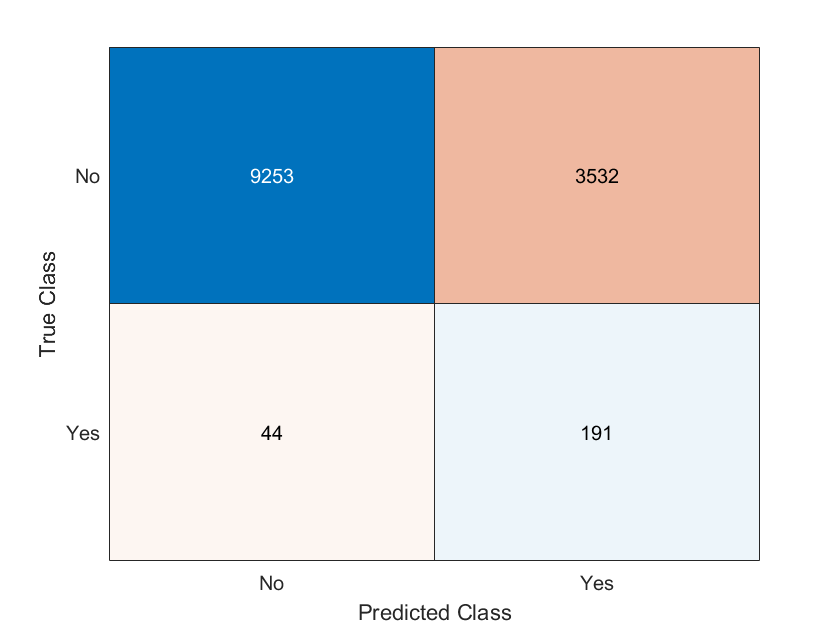

rng(13)
% split in train and test set
part=cvpartition(group,'HoldOut',.3, 'Stratify',true); % stratify to make sure same priors
ids_train=training(part);
ids_test=test(part);

svm1=fitcsvm(features(ids_train,:),group(ids_train), ...
    'BoxConstraint',1, ...
    'CategoricalPredictors',{'hypertension','smoking_status','heart_disease'}, ...
    'KernelFunction','linear', ...
    'Cost',[0 1;55 0]);

[preds1, postprob1]=predict(svm1,features(ids_test,:));
% model...........
% svm1.ModelParameters
% assessment...........
confusionchart(group(ids_test,:),preds1);

c=confusionmatStats(group(ids_test,:),preds1);
accuracy=c.accuracy; sensitivity=c.sensitivity; specificity=c.specificity; Fscore=c.Fscore;
table(accuracy,sensitivity,specificity,Fscore,'RowNames',{'Class No','Class Yes'})

ans = 2×4 table
                 accuracy    sensitivity    specificity     Fscore 
                 ________    ___________    ___________    ________
    Class No     0.72535       0.72374        0.81277       0.83806
    Class Yes    0.72535       0.81277        0.72374      0.096513

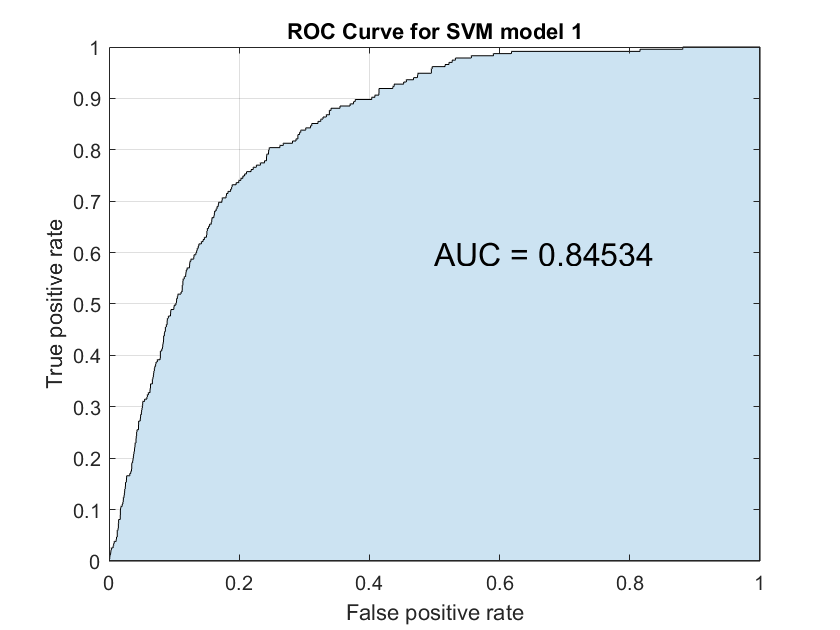


% ROC...........
[FPR1, TPR1, ~, AUC1]=perfcurve(group(ids_test),postprob1(:,2),'Yes');
area(FPR1,TPR1,'FaceColor',[0.8 0.89 0.95]);
grid on
text(.5,.6,['AUC = ' num2str(AUC1)],"FontSize",16);
xlabel('False positive rate')
ylabel('True positive rate') 
title('ROC Curve for SVM model 1')

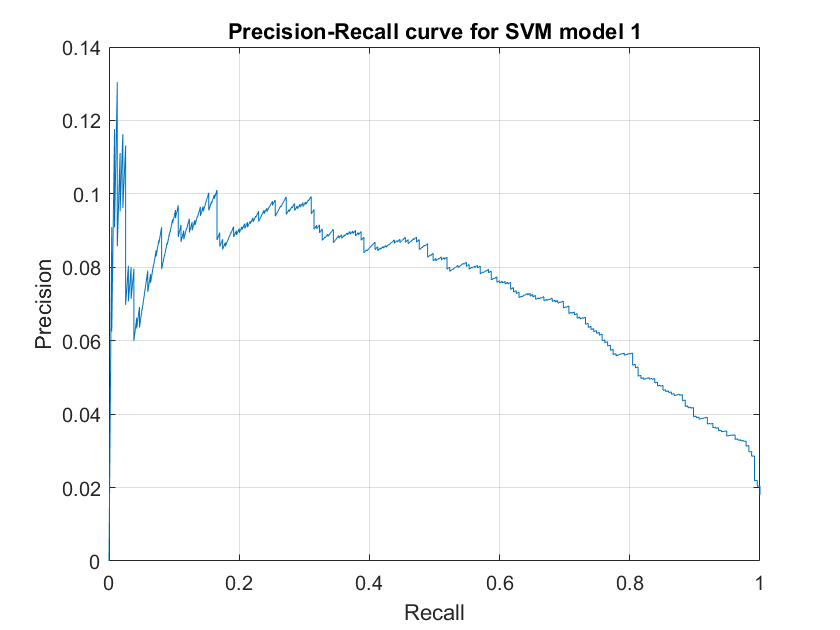

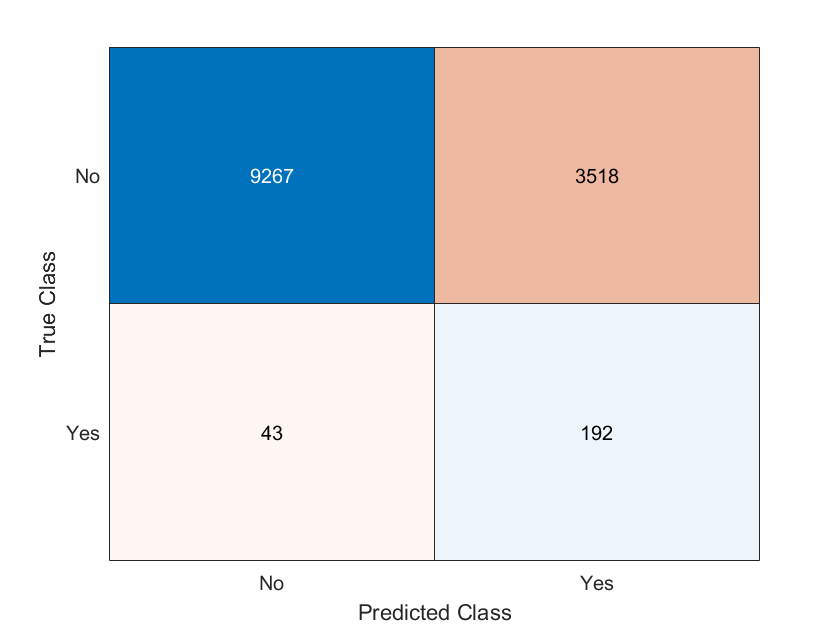

ans = 2×4 table
                 accuracy    sensitivity    specificity     Fscore 
                 ________    ___________    ___________    ________
    Class No      0.7265       0.72483        0.81702       0.83883
    Class Yes     0.7265       0.81702        0.72483      0.097338

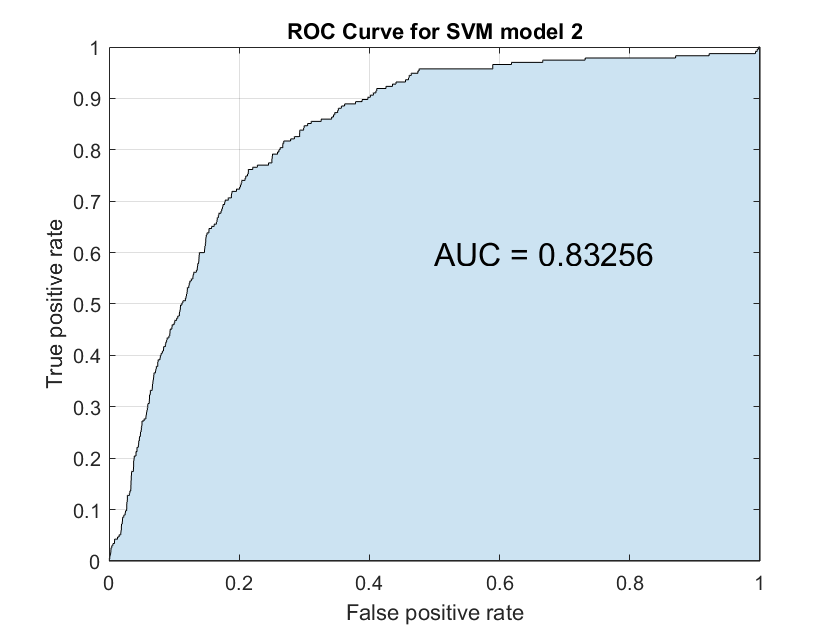

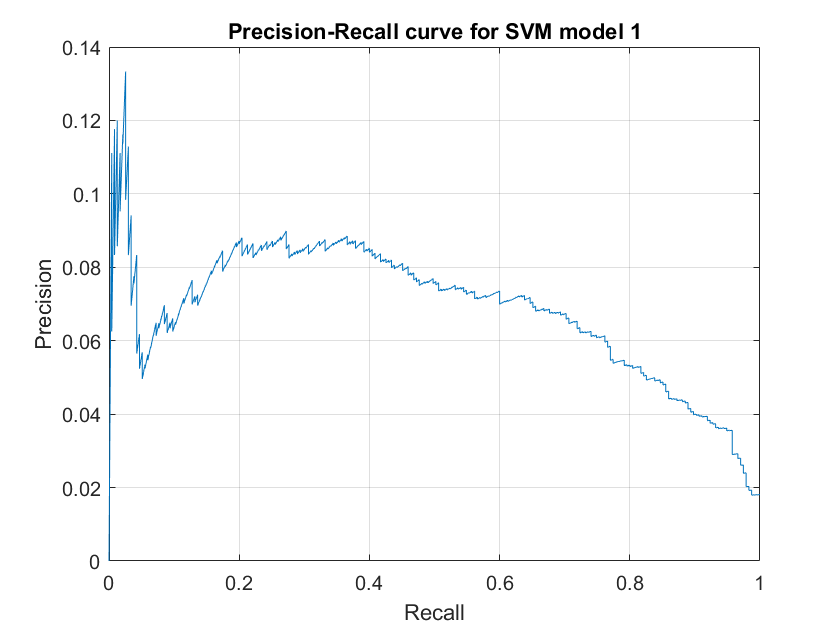


% Precision-Recall curve...........
[REC, PREC, ~, AUC2]=perfcurve(group(ids_test),postprob1(:,2),'Yes', ...
    'XCrit','reca','YCrit','prec');
plot(REC,PREC)
grid on
xlabel('Recall')
ylabel('Precision') 
title('Precision-Recall curve for SVM model 1')

Buscar kernel más adecuado

|========================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | KernelFuncti-|
|      | result |             | runtime     | (observed)  | on           |
|========================================================================|
|    1 | Best   |     0.22761 |      377.75 |     0.22761 |   polynomial |


|    2 | Best   |     0.22527 |      55.434 |     0.22527 |     gaussian |


|    3 | Best   |     0.22069 |      59.088 |     0.22069 |       linear |


|    4 | Accept |     0.22069 |      59.122 |     0.22069 |       linear |


|    5 | Accept |     0.22761 |      370.89 |     0.22069 |   polynomial |


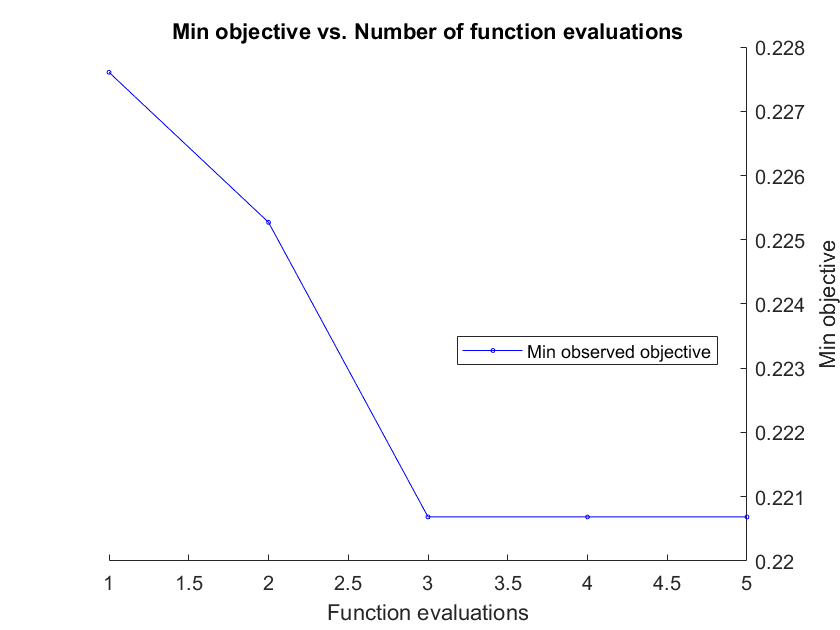


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 5 reached.
Total function evaluations: 5
Total elapsed time: 926.3402 seconds
Total objective function evaluation time: 922.2875

Best observed feasible point:
    KernelFunction
    ______________
        linear    
Observed objective function value = 0.22069
Function evaluation time = 59.0878



svm1=fitcsvm(features(ids_train,:),group(ids_train), ...
    'CategoricalPredictors',{'hypertension','smoking_status','heart_disease'}, ...
    'Cost',[0 1;55 0], ...
    'OptimizeHyperparameters',{'KernelFunction'}, ...
    'HyperparameterOptimizationOptions', struct('Optimizer','gridsearch', ...
                                                'MaxObjectiveEvaluations',5));

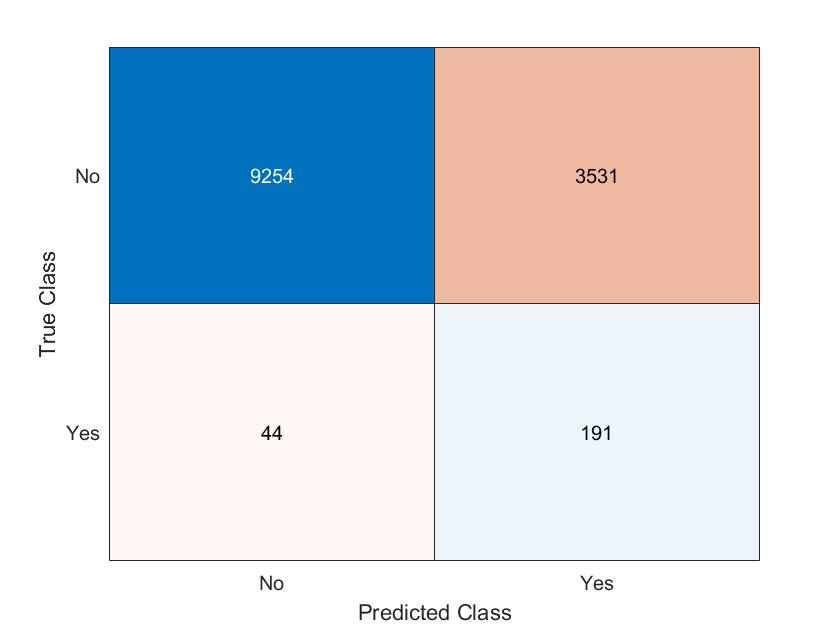


[preds1, postprob1]=predict(svm1,features(ids_test,:));
% model...........
% svm1.ModelParameters
% assessment...........
confusionchart(group(ids_test,:),preds1);

c=confusionmatStats(group(ids_test,:),preds1);
accuracy=c.accuracy; sensitivity=c.sensitivity; specificity=c.specificity; Fscore=c.Fscore;
table(accuracy,sensitivity,specificity,Fscore,'RowNames',{'Class No','Class Yes'})

ans = 2×4 table
                 accuracy    sensitivity    specificity     Fscore 
                 ________    ___________    ___________    ________
    Class No     0.72542       0.72382        0.81277       0.83811
    Class Yes    0.72542       0.81277        0.72382      0.096538

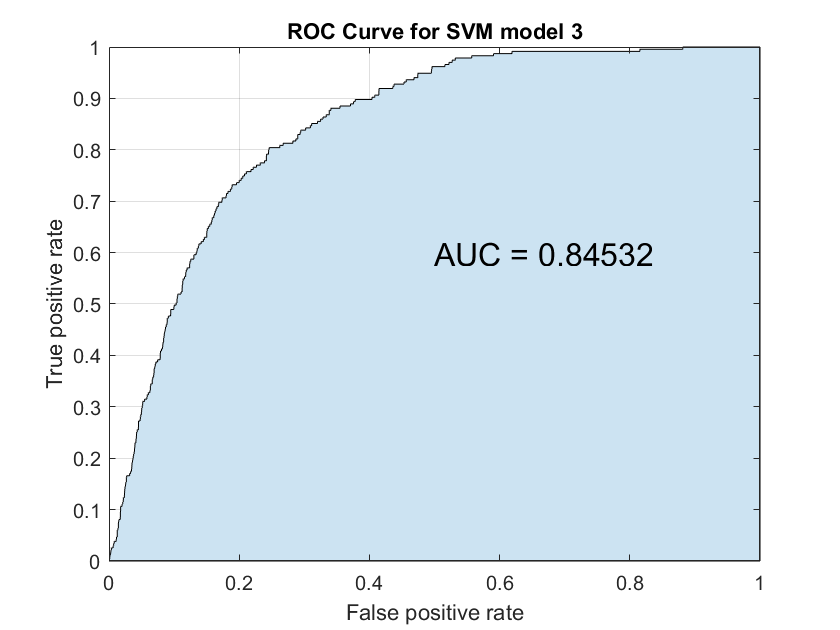


% ROC...........
[FPR, TPR, ~, AUC]=perfcurve(group(ids_test),postprob1(:,2),'Yes');
area(FPR,TPR,'FaceColor',[0.8 0.89 0.95]);
grid on
text(.5,.6,['AUC = ' num2str(AUC)],"FontSize",16);
xlabel('False positive rate')
ylabel('True positive rate') 
title('ROC Curve for SVM model 3')

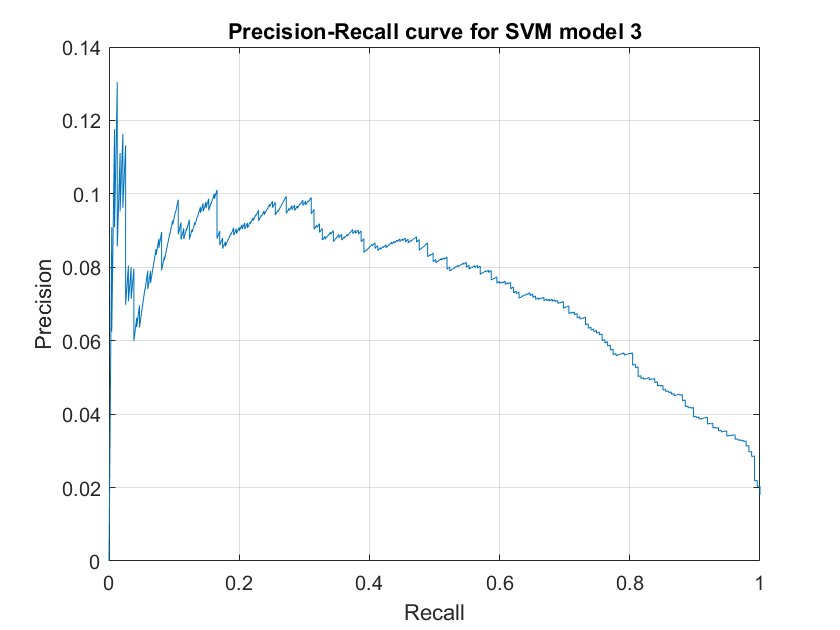

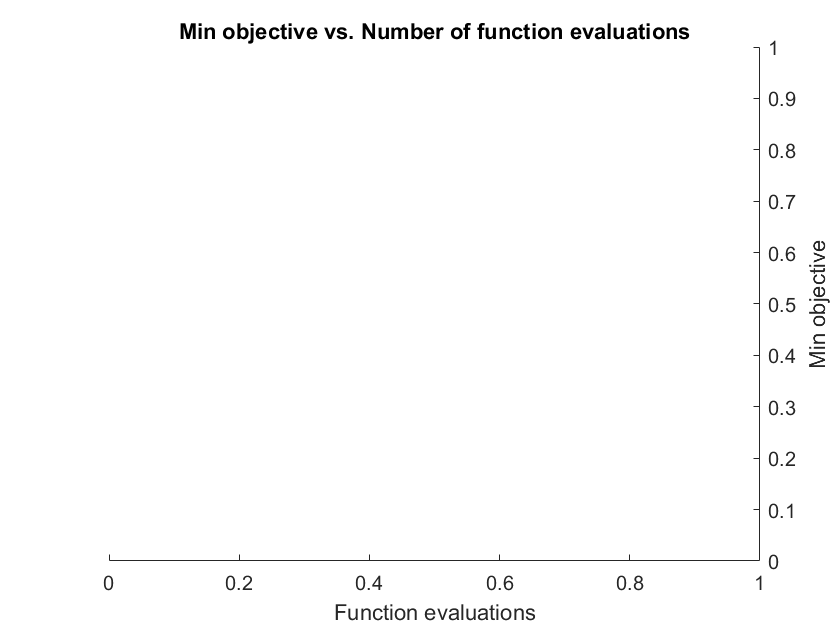


% Precision-Recall curve...........
[REC, PREC, ~, AUC2]=perfcurve(group(ids_test),postprob1(:,2),'Yes', ...
    'XCrit','reca','YCrit','prec');
plot(REC,PREC)
grid on
xlabel('Recall')
ylabel('Precision') 
title('Precision-Recall curve for SVM model 3')

Buscar valor de 'BoxConstraint' más adecuado (parámetro C)

|========================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BoxConstraint|
|      | result |             | runtime     | (observed)  |              |
|========================================================================|
|    1 | Best   |     0.22062 |      324.43 |     0.22062 |       14.072 |


|    2 | Accept |     0.22179 |      38.351 |     0.22062 |     0.017028 |


|    3 | Accept |     0.22629 |      43.901 |     0.22062 |    0.0014349 |


|    4 | Accept |     0.22084 |      47.806 |     0.22062 |      0.59913 |


|    5 | Best   |     0.22034 |      47.951 |     0.22034 |      0.23966 |


|    6 | Accept |     0.23011 |      39.393 |     0.22034 |    0.0024968 |


|    7 | Accept |     0.22072 |      71.128 |     0.22034 |      0.93678 |


|    8 | Accept |     0.22479 |      45.958 |     0.22034 |    0.0011368 |


|    9 | Accept |     0.22571 |      41.075 |     0.22034 |    0.0012279 |


|   10 | Accept |     0.22197 |        2025 |     0.22034 |       552.51 |


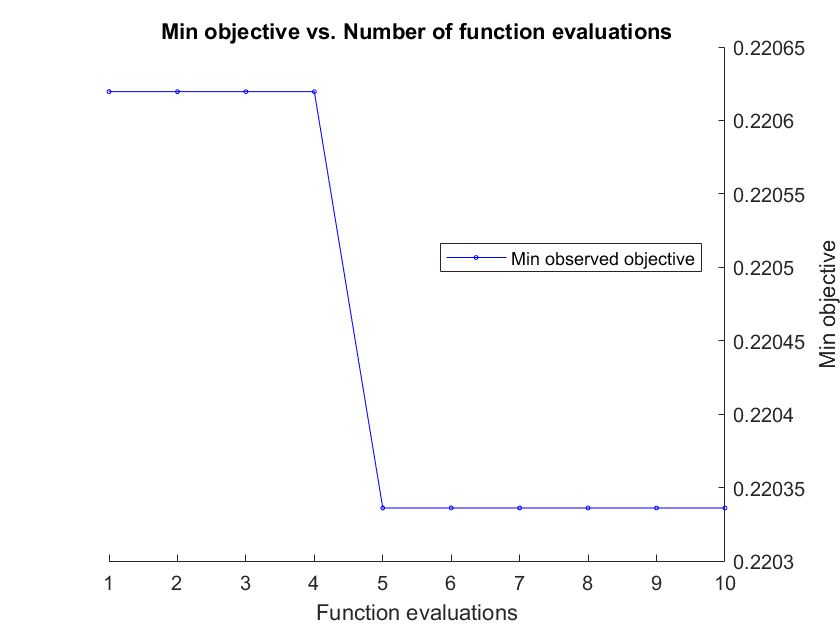


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 10 reached.
Total function evaluations: 10
Total elapsed time: 2734.3555 seconds
Total objective function evaluation time: 2725.0111

Best observed feasible point:
    BoxConstraint
    _____________

       0.23966   

Observed objective function value = 0.22034
Function evaluation time = 47.9505



features=stroke(:,["age","avg_glucose_level","hypertension", ...
    "smoking_status","heart_disease"]);
cuanti=["age","avg_glucose_level"];
features(:,cuanti)=normalize(features(:,cuanti),"range");
group=stroke.stroke;

rng(13)
% split in train and test set
part=cvpartition(group,'HoldOut',.3, 'Stratify',true); % stratify to make sure same priors
ids_train=training(part);
ids_test=test(part);

svmopt=fitcsvm(features(ids_train,:),group(ids_train), ...
    'CategoricalPredictors',{'hypertension','smoking_status','heart_disease'}, ...
    'KernelFunction','linear', ...
    'Cost',[0 1;55 0], ...
    'OptimizeHyperparameters',{'BoxConstraint'}, ...
    'HyperparameterOptimizationOptions', struct('Optimizer','randomsearch', ...
                                                'MaxObjectiveEvaluations',10));

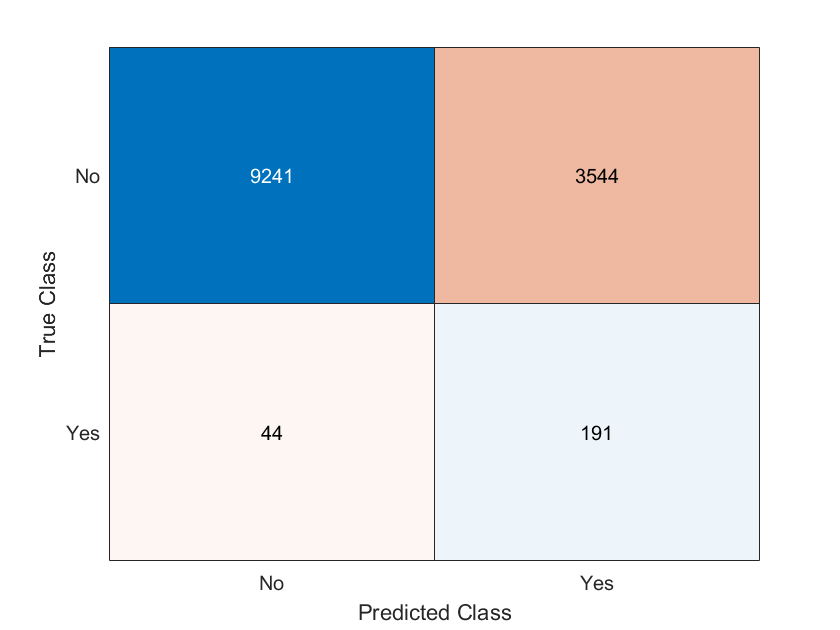


[predsopt, postprobopt]=predict(svmopt,features(ids_test,:));
% model...........
% svm1.ModelParameters
% assessment...........
confusionchart(group(ids_test,:),predsopt);

c=confusionmatStats(group(ids_test,:),predsopt);
accuracy=c.accuracy; sensitivity=c.sensitivity; specificity=c.specificity; Fscore=c.Fscore;
table(accuracy,sensitivity,specificity,Fscore,'RowNames',{'Class No','Class Yes'})

ans = 2×4 table
                 accuracy    sensitivity    specificity     Fscore 
                 ________    ___________    ___________    ________

    Class No     0.72442        0.7228        0.81277       0.83743
    Class Yes    0.72442       0.81277         0.7228      0.096222


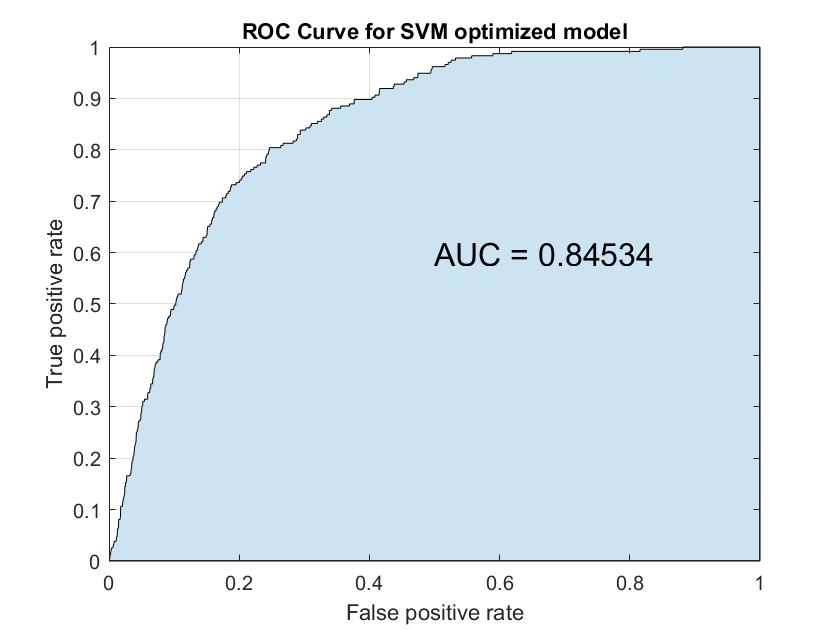


% ROC...........
[FPRopt, TPRopt, ~, AUCopt]=perfcurve(group(ids_test),postprobopt(:,2),'Yes');
area(FPRopt,TPRopt,'FaceColor',[0.8 0.89 0.95]);
grid on
text(.5,.6,['AUC = ' num2str(AUCopt)],"FontSize",16);
xlabel('False positive rate')
ylabel('True positive rate') 
title('ROC Curve for SVM optimized model')


% Precision-Recall curve...........
% [RECopt, PRECopt, ~, AUCopt2]=perfcurve(group(ids_test),postprobopt(:,2),'Yes', ...
%     'XCrit','reca','YCrit','prec');
% plot(RECopt,PRECopt)
% grid on
% xlabel('Recall')
% ylabel('Precision') 
% title('Precision-Recall curve for SVM optimized model')

Validación cruzada con parámetros óptimos

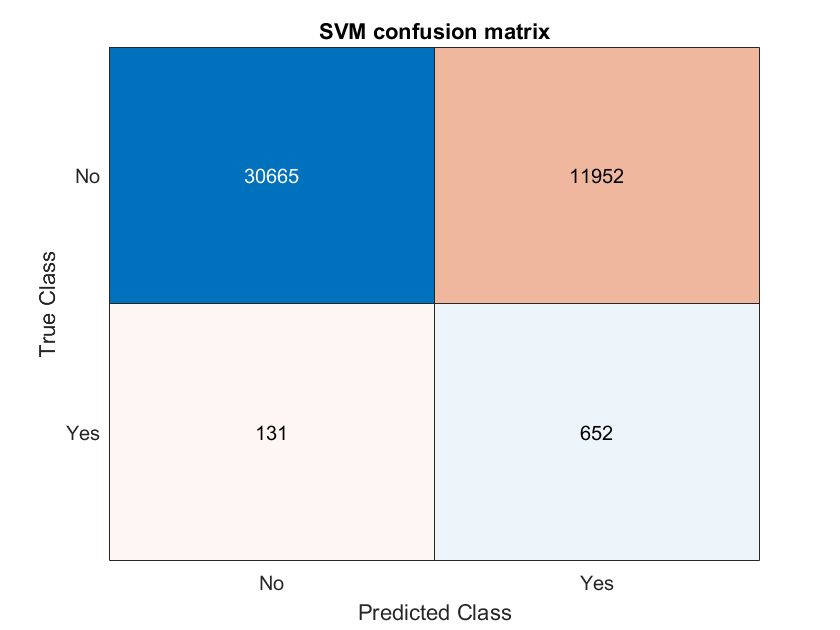

rng(13)
SVM=fitcsvm(features,group, ...
    'CategoricalPredictors',{'hypertension','smoking_status','heart_disease'}, ...
    'BoxConstraint', 0.24, ...
    'KernelFunction','linear', ...
    'CrossVal','on', ...
    'Cost',[0 1;55 0]);

% predictions ............
[predsSVM, postprSVM]=kfoldPredict(SVM);

% assessment ..............
confusionchart(group,predsSVM);
title('SVM confusion matrix')

c=confusionmatStats(group,predsSVM);
accuracy=c.accuracy; sensitivity=c.sensitivity; specificity=c.specificity; Fscore=c.Fscore;
table(accuracy,sensitivity,specificity,Fscore,'RowNames',{'Class No','Class Yes'})

ans = 2×4 table
                 accuracy    sensitivity    specificity     Fscore 
                 ________    ___________    ___________    ________
    Class No     0.72159       0.71955        0.83269       0.83541
    Class Yes    0.72159       0.83269        0.71955      0.097408

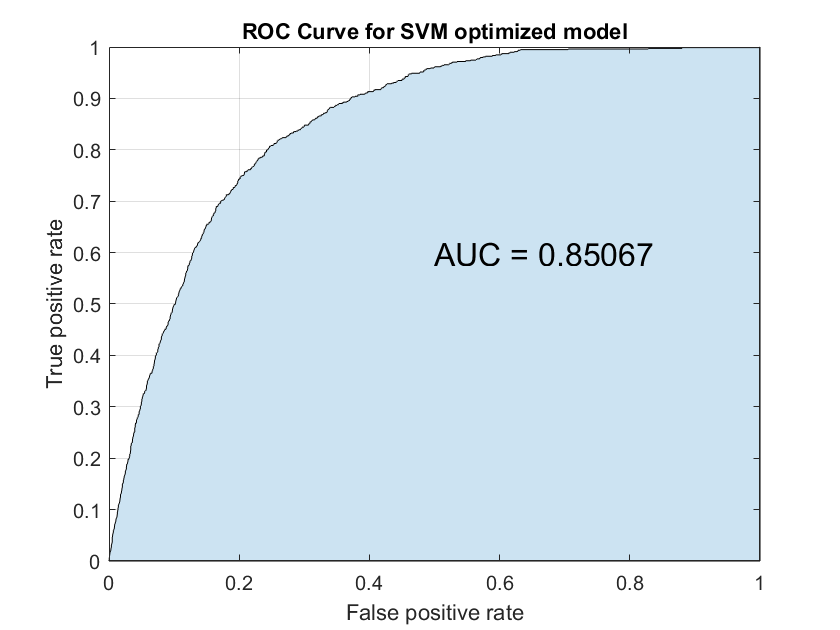


% ROC .................
[FPRSVM, TPRSVM, ~, AUCSVM]=perfcurve(group,postprSVM(:,2),'Yes');
area(FPRSVM,TPRSVM,'FaceColor',[0.8 0.89 0.95]);
grid on
text(.5,.6,['AUC = ' num2str(AUCSVM)],"FontSize",16);
xlabel('False positive rate')
ylabel('True positive rate') 
title('ROC Curve for SVM optimized model')